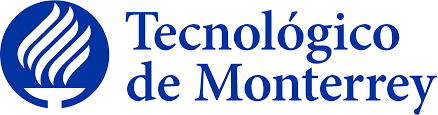

### Implementación de robótica inteligente (TE3002B)

## Actividad 1.12 (Modelado Cinemático de Piernas)

Pamela Hernández Montero A01736368

Obtener la matriz de transformación homogénea T de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base). Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

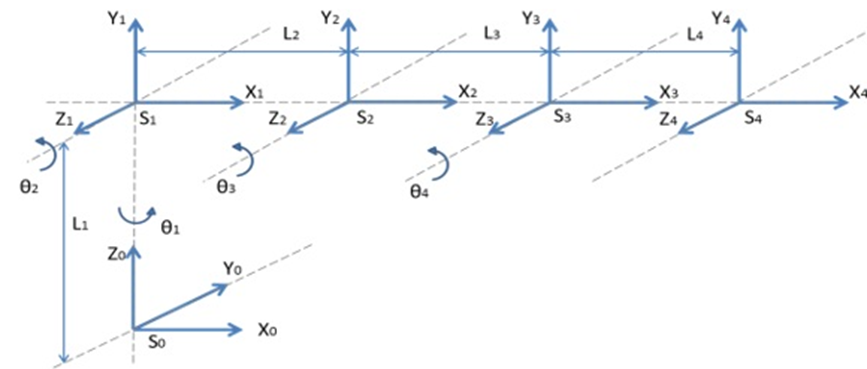

Para la primera figura realicé las transformaciones homogéneas que consisten en:

- Rotación en el eje X de 90 grados y una traslación de 0.5 unidades en el eje Z.

- Traslación de 0.5 unidades en el eje X.

- Traslación de 0.5 unidades en el eje X.

- Traslación de 0.5 unidades en el eje X.

Posteriormente, para todas las figuras, determine la matriz de transformación homogénea global a partir de las matrices de transformación individuales. Esto se logra multiplicando las matrices de transformación homogénea sucesivas para obtener la posición y orientación final de la figura respecto al sistema de coordenadas global.

Después, para cada ejercicio, grafique una estructura que representa la longitud recorrida por la matriz de transformación para finalmente, observar el movimiento completo del objeto a través del espacio tridimensional usando tranimate.

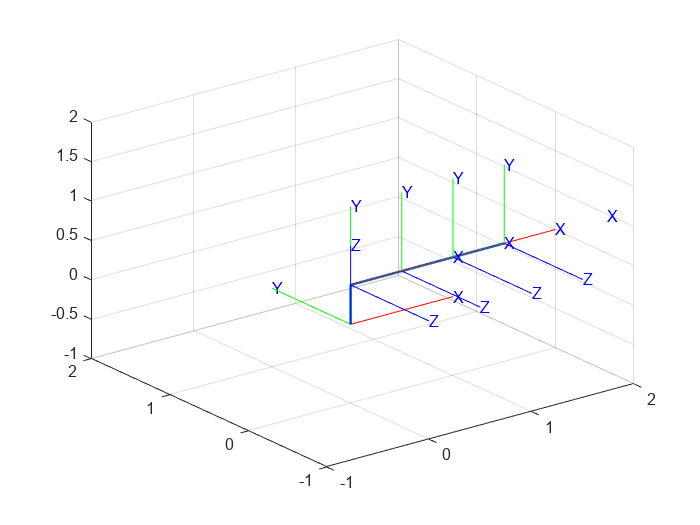

Matriz de transformación homogénea
    1         0         0       1.5
    0         0        -1         0
    0         1         0       0.5
    0         0         0         1


% Limpieza de pantalla
clear all
close all
clc

% Calculamos las matrices de transformación homogénea
H0 = SE3;
H1 = SE3(rotx(pi/2), [0 0 0.5]);
H2 = SE3(rotz(0), [0.5 0 0]);
H3 = SE3(rotz(0), [0.5 0 0]);
H4 = SE3(rotz(0), [0.5 0 0]);

H10 = H0 * H1;
H20 = H10 * H2;
H30 = H20 * H3;
H40 = H30 * H4; % Matriz de transformación homogénea global de 4 a 0

% Coordenadas de la estructura de translación y rotación
x = [0 0 0.5 1 1.5 1.5];
y = [0 0 0 0 0 0];
z = [0 0.5 0.5 0.5 0.5 0.5];

plot3(x, y, z, 'LineWidth', 1.5); axis([-1 2 -1 2 -1 2]); grid on;
hold on;

% Graficamos la trama absoluta o global 
trplot(H0, 'rgb', 'axis', [-1 2 -1 2 -1 2]);

% Realizamos una animación para las tramas
tranimate(H0, H10, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H10, H20, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H20, H30, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H30, H40, 'rgb', 'axis', [-1 4 -1 6 -1 2]);disp("Matriz de transformación homogénea");disp(H40);

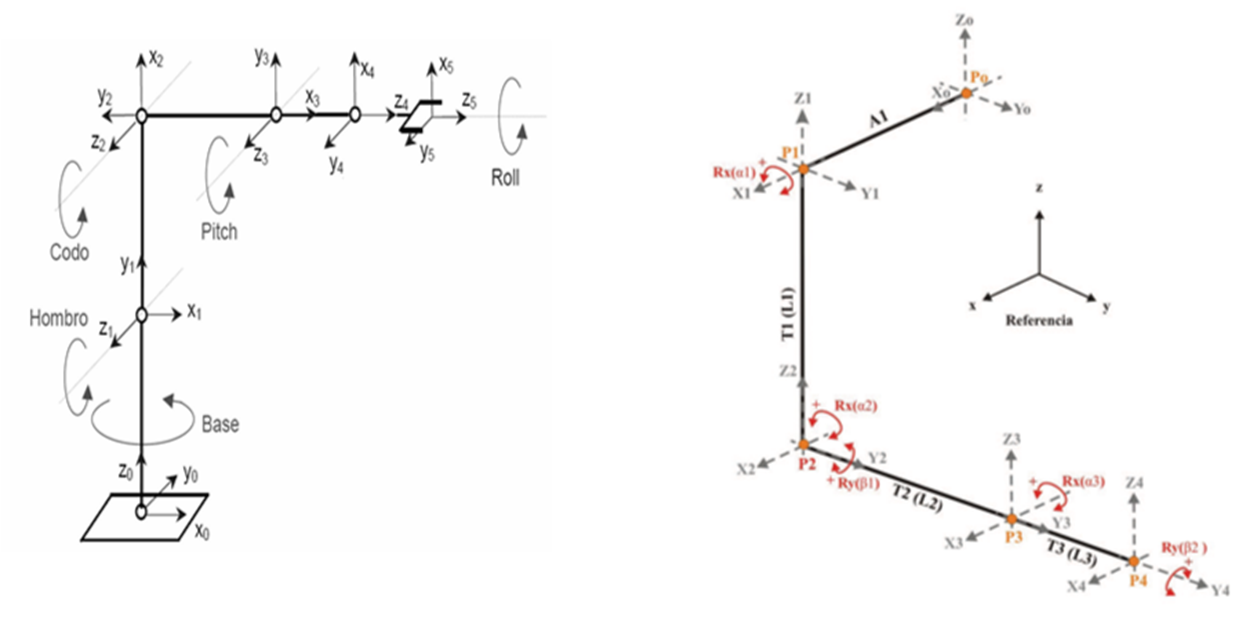

Para la segunda figura realicé las transformaciones homogéneas que consisten en:

- Rotación en el eje X de 90 grados y una traslación de 0.5 unidades en el eje Z.

- Rotación en el eje Z de 90 grados y una traslación de 0.5 unidades en el eje Y.

- Rotación en el eje Z de -90 grados y una traslación de -1 unidad en el eje Y.

- Rotación en el eje Z de 90 grados y una traslación de 0.5 unidades en el eje X.

- Rotación en el eje X de 90 grados sin traslación.

- Traslación de 0.5 unidades en el eje Z sin rotación.

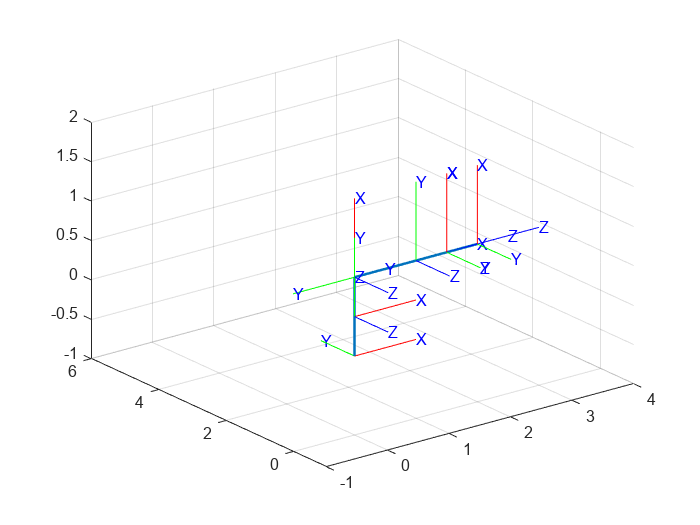

Matriz de transformación homogénea
    0         0         1         2
    0        -1         0         0
    1         0         0         1
    0         0         0         1


% Limpieza de pantalla
clear all
close all
clc

% Calculamos las matrices de transformación homogénea
H0 = SE3;
H1 = SE3(rotx(pi/2), [0 0 0.5]);
H2 = SE3(rotz(pi/2), [0 0.5 0]);
H3 = SE3(rotz(-pi/2), [0 -1 0]);
H4 = SE3(rotz(pi/2), [0.5 0 0]);
H5 = SE3(rotx(pi/2), [0 0 0]);
H6 = SE3(rotx(0), [0 0 0.5]);

H10 = H0 * H1;
H20 = H10 * H2;
H30 = H20 * H3;
H40 = H30 * H4;
H50 = H40 * H5;
H60 = H50 * H6; % Matriz de transformación homogénea global de 6 a 0

% Coordenadas de la estructura de translación y rotación
x = [0 0 2];
y = [0 0 0];
z = [0 1 1 ];

plot3(x, y, z, 'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

% Graficamos la trama absoluta o global 
trplot(H0, 'rgb', 'axis', [-1 4 -1 2 -1 2]);

% Realizamos una animación para las tramas
tranimate(H0, H10, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H10, H20, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H20, H30, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H30, H40, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H40, H50, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H50, H60, 'rgb', 'axis', [-1 4 -1 6 -1 2]);disp("Matriz de transformación homogénea");disp(H60);

Para la ultima figura realicé las transformaciones homogéneas que consisten en:

- Rotación en el eje Z de -180 grados y una traslación en el origen.

- Traslación de 0.5 unidades en el eje X.

- Traslación de -0.5 unidades en el eje Z.

- Traslación de 1 unidad en el eje Y.

- Traslación de 0.5 unidades en el eje Y.

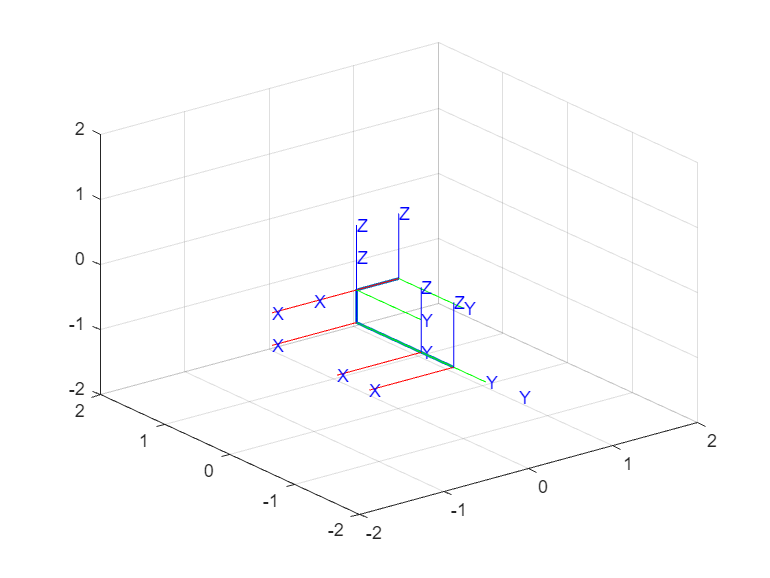

Matriz de transformación homogénea
    -1         0         0      -0.5
     0        -1         0      -1.5
     0         0         1      -0.5
     0         0         0         1


% Limpieza de pantalla
clear all
close all
clc

% Calculamos las matrices de transformación homogénea
H0 = SE3(rotz(-pi), [0 0 0]);
H1 = SE3(rotz(0), [0.5 0 0]);
H2 = SE3(rotz(0), [0 0 -0.5]);
H3 = SE3(rotz(0), [0 1 0]);
H4 = SE3(rotx(0), [0 0.5 0]);

H10 = H0 * H1;
H20 = H10 * H2;
H30 = H20 * H3;
H40 = H30 * H4; % Matriz de transformación homogénea global de 6 a 0

% Coordenadas de la estructura de translación y rotación
x = [0  -0.5  -0.5 -0.5];
y = [0    0     0   -1.5 ];
z = [0    0   -0.5 -0.5 ];

plot3(x, y, z, 'LineWidth', 1.5); axis([-2 2 -2 2 -2 2]); grid on;
hold on;

% Graficamos la trama absoluta o global 
trplot(H0, 'rgb', 'axis', [-1 4 -1 6 -1 2]);

% Realizamos una animación para las tramas
tranimate(H0, H10, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H10, H20, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H20, H30, 'rgb', 'axis', [-1 4 -1 6 -1 2]);
tranimate(H30, H40, 'rgb', 'axis', [-1 4 -1 6 -1 2]); disp("Matriz de transformación homogénea");disp(H40);

Este trabajo no fue difícil de realizar debido a que tenía conocimientos previos sobre las transformaciones de matrices homogéneas en un espacio tridimensional, sin embargo, presenté problemas al realizar la rotación debido a las librerías, por lo que las instalé desde repositorios que el autor dejó en Github. A pesar de estos inconvenientes, logré implementar correctamente las transformaciones homogéneas para cada figura, y grafiqué las estructuras correspondientes para representar la longitud recorrida por la matriz de transformación.